T = 0.03;
%delovna točka
U00 = 5.1

U00 = 5.1000

Y00 = 5.3464

Y00 = 5.3464

t = 0:T:60;
simin_val = 5.1:0.25:6.1;
simin = simin_val'

simin =     5.1000
    5.3500
    5.6000
    5.8500
    6.1000


% mrtva cona se konča pri 4.6
% gremo do cca 7
% najprej probat na 0.25V natančno

% vhodni signal
toWorkspace = 5;

Y_all = [Y_46.Data,Y_485.Data,Y_51.Data,Y_535.Data,Y_56.Data,Y_585.Data,Y_61.Data,Y_635.Data,Y_66.Data,Y_685.Data];

Y_end = mean(Y_all(end-30:end,:),1)

Y_end =     5.6999    5.5048    5.3464    5.2165    5.0422    4.8892    4.7480    4.5761    4.4444    4.2483


Y_start =     5.7927    5.8007    5.8065    5.8282    5.8361    5.7937    5.7978    5.8318    5.8346    5.8315


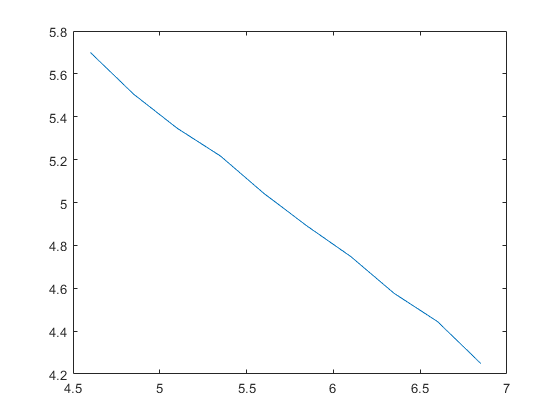

plot(simin_val,Y_end)

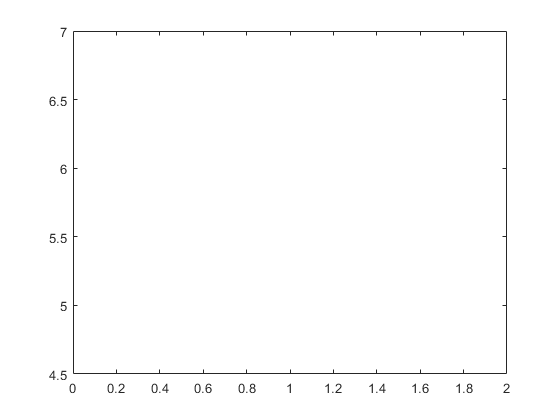


plot(Y_all(3))

%plot(Y_56.Data)
U_PRBS = prbs(10) + 5.1

U_PRBS =     6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000


U_PRBS_T = prbs(10) + 5.1

U_PRBS_T =     6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000
    6.1000


U = ones(7500,1)*5.1

U =     5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000


U_T = ones(length(t)-length(U_PRBS_T),1)*5.1

U_T =     5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000


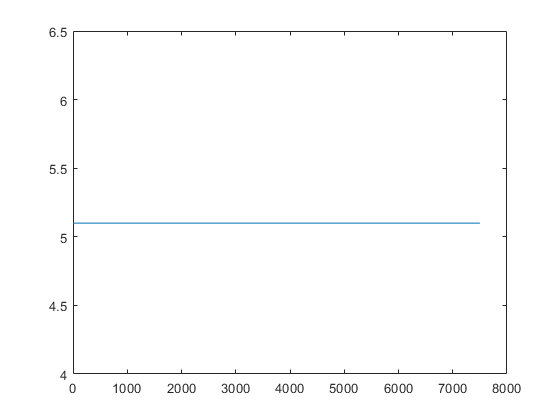


plot(U)

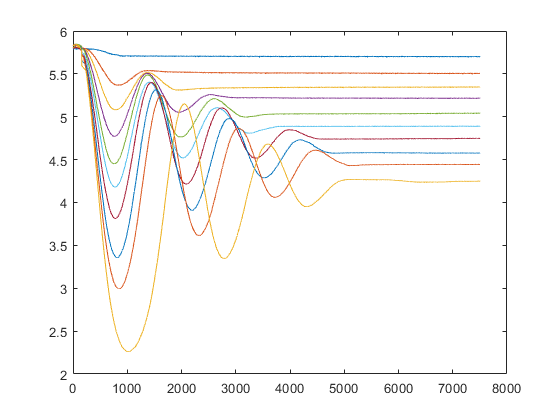

figure
%plot(U_PRBS)
plot(Y_all)

U_prbs = [U;U_PRBS]

U_prbs =     5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000


U_prbs_T = [U_T;U_PRBS_T]

U_prbs_T =     5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000


U_prbs_11 = [U;prbs(11)+5.1]

U_prbs_11 =     5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000


U_prbs_12 = [U;prbs(12)+5.1]

U_prbs_12 =     5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000
    5.1000


%plot(U_prbs)

PRBS_true = [t',U_prbs_T]

PRBS_true =          0    5.1000
    0.0300    5.1000
    0.0600    5.1000
    0.0900    5.1000
    0.1200    5.1000
    0.1500    5.1000
    0.1800    5.1000
    0.2100    5.1000
    0.2400    5.1000
    0.2700    5.1000


% plot(out.simout)
exp_1 = [PRBS_true,out.simout.Data]

exp_1 =          0    5.1000    5.8511
    0.0300    5.1000    5.8514
    0.0600    5.1000    5.8514
    0.0900    5.1000    5.8514
    0.1200    5.1000    5.8624
    0.1500    5.1000    5.8557
    0.1800    5.1000    5.8575
    0.2100    5.1000    5.8524
    0.2400    5.1000    5.8545
    0.2700    5.1000    5.8572
